# Acticidad 6.1: Seguimiento de Trayectorias

**Paola Rojas Domínguez A01737136**

## Inicialización

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores.

clear all
close all
clc

## a) $x=2\cos \left(0\ldotp 2t\right),y=2\textrm{sen}\left(0\ldotp 4t\right)$

### Tiempo

Se definen los parámetros temporales del experimento: duración total (`tf`), intervalo de muestreo (`ts`), y se genera el vector de tiempo (`t`) con su longitud total (`N`), que define la cantidad de pasos de simulación.

tf=35;             % Tiempo de simulación en segundos (s)
ts=0.05;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

### Condiciones iniciales

Se establecen las condiciones iniciales del robot: su posición en el plano (x, y) y su orientación (`phi`) medida en radianes. En este caso, el robot comienza en el origen apuntando hacia

x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

Inicialmente, la posición del punto de control del robot coincide con su posición actual (`hx`, `hy`).

hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

### Trayectoria Deseada

Ecuaciones paramétricas de la trayectoria deseada

hxd=2*cos(0.2*t);
hyd=2*sin(0.4*t);

%Velocidades de la trayectoria deseada
hxdp = diff(hxd) / ts;
hydp = diff(hyd) / ts;

% Para que hxdp y hydp tengan la misma longitud que t, añadimos el último valor
hxdp = [hxdp, hxdp(end)];
hydp = [hydp, hydp(end)];

### Control, bucle de simulación

Se implementa un bucle `for` que recorre todos los instantes de tiempo definidos en el vector `t`. Dentro de este ciclo, se realiza el cálculo de errores de posición, la matriz Jacobiana, las ganancias, y la ley de control para determinar las velocidades lineal y angular requeridas para que el robot siga la trayectoria deseada.

for k=1:N

#### a) Errores de control

 Se calculan los errores de posición entre la trayectoria deseada y la actual.

    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

#### b) Matriz Jacobiana

 Se construye la matriz Jacobiana que transforma errores en el marco global a comandos de movimiento en el marco del robot.

    J=[cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];

#### c) Matriz de Ganancias

Se define una ganancia proporcional para corregir el error.

    K=[12 0; 0 12];

####  d) Velocidades deseadas

 Se obtienen las velocidades de la trayectoria de referencia.

    hdp=[hxdp(k);hydp(k)];

#### e) Ley de Control

 Calcula las velocidades de referencia para el robot, corrigiendo el error e incorporando la velocidad deseada.

    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 

#### Aplicación de Control al Robot

Una vez calculadas las velocidades de control, se aplican al modelo cinemático del robot mediante integración numérica (Método de Euler) para actualizar su posición y orientación en cada instante de tiempo.

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-3 3 -3 3 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

**b) Graficar robots en la posicion inicial**

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

**c) Graficar trayectorias**

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'c','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial

**d) Bucle de simulacion de movimiento del robot**

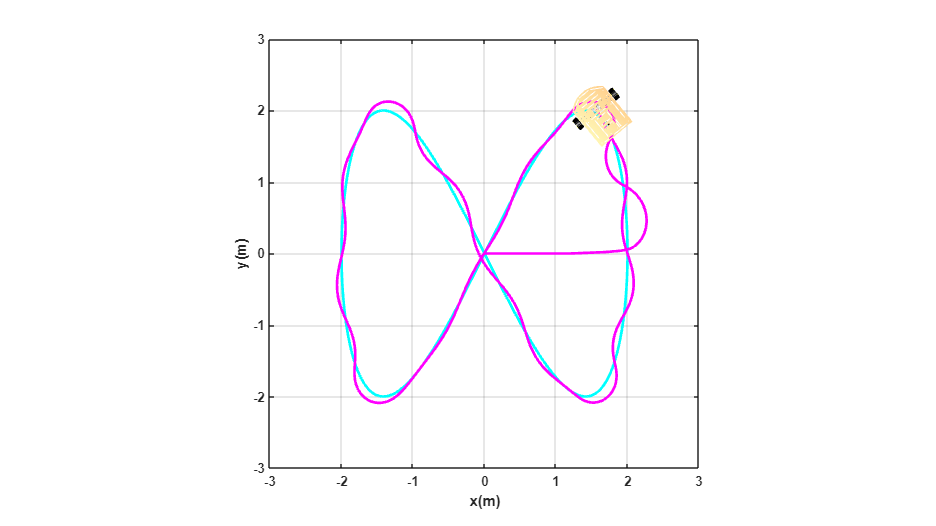

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'m','lineWidth',2);
    
    pause(ts);

end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

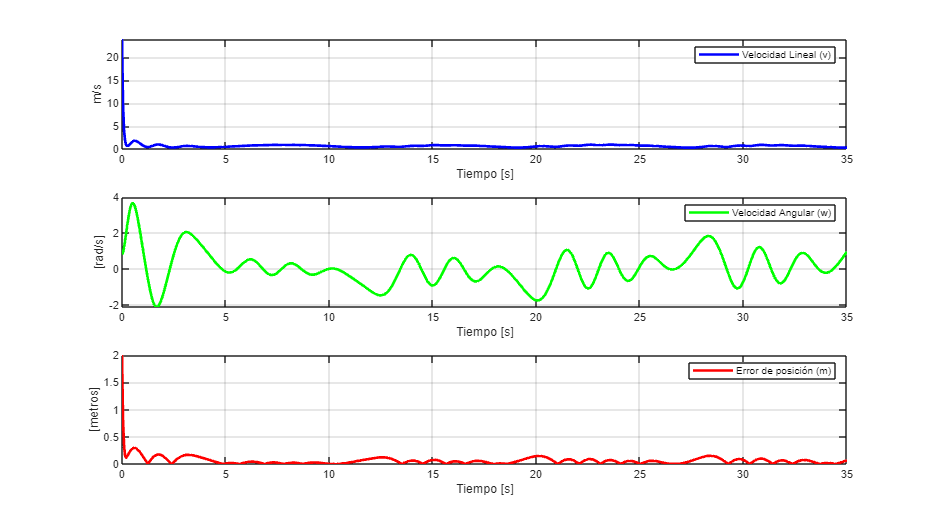

graph=figure;  % Crear figura
set(graph,'position',sizeScreen); % Configurar tamaño de la figura
subplot(311)
plot(t(1:N),v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:N),w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:N),Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

## **b) **$x=t-3\textrm{sen}\left(t\right),y=4-3\cos \left(t\right)$

### Tiempo

Se definen los parámetros temporales del experimento: duración total (`tf`), intervalo de muestreo (`ts`), y se genera el vector de tiempo (`t`) con su longitud total (`N`), que define la cantidad de pasos de simulación.

tf=40;             % Tiempo de simulación en segundos (s)
ts=0.05;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

### Condiciones iniciales

Se establecen las condiciones iniciales del robot: su posición en el plano (x, y) y su orientación (`phi`) medida en radianes. En este caso, el robot comienza en el origen apuntando hacia

x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

Inicialmente, la posición del punto de control del robot coincide con su posición actual (`hx`, `hy`).

hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

### Trayectoria Deseada

Ecuaciones paramétricas de la trayectoria deseada

hxd=t-3*sin(t);
hyd=4-3*cos(t);

%Velocidades de la trayectoria deseada
hxdp = diff(hxd) / ts;
hydp = diff(hyd) / ts;

% Para que hxdp y hydp tengan la misma longitud que t, añadimos el último valor
hxdp = [hxdp, hxdp(end)];
hydp = [hydp, hydp(end)];

### Control, bucle de simulación

Se implementa un bucle `for` que recorre todos los instantes de tiempo definidos en el vector `t`. Dentro de este ciclo, se realiza el cálculo de errores de posición, la matriz Jacobiana, las ganancias, y la ley de control para determinar las velocidades lineal y angular requeridas para que el robot siga la trayectoria deseada.

for k=1:N 

#### a) Errores de control

 Se calculan los errores de posición entre la trayectoria deseada y la actual.

    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

#### b) Matriz Jacobiana

 Se construye la matriz Jacobiana que transforma errores en el marco global a comandos de movimiento en el marco del robot.

    J=[cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];

#### c) Matriz de Ganancias

Se define una ganancia proporcional para corregir el error.

    K=[13 0;...
       0 13];

####  d) Velocidades deseadas

 Se obtienen las velocidades de la trayectoria de referencia.

    hdp=[hxdp(k);hydp(k)];

#### e) Ley de Control

 Calcula las velocidades de referencia para el robot, corrigiendo el error e incorporando la velocidad deseada.

    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 

#### Aplicación de Control al Robot

Una vez calculadas las velocidades de control, se aplican al modelo cinemático del robot mediante integración numérica (Método de Euler) para actualizar su posición y orientación en cada instante de tiempo.

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-5 40 -5 40 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

**b) Graficar robots en la posicion inicial**

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

**c) Graficar trayectorias**

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'c','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial

**d) Bucle de simulacion de movimiento del robot**

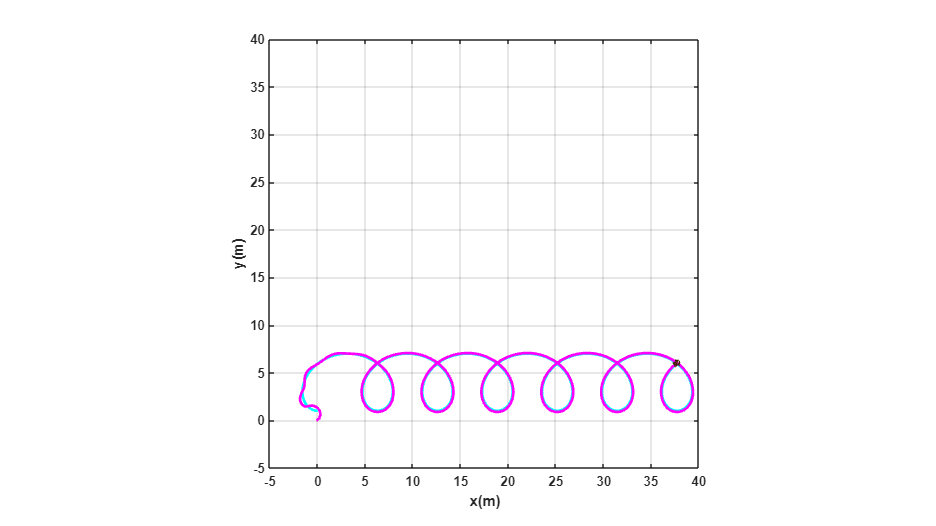

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'m','lineWidth',2);
    
    pause(ts);

end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

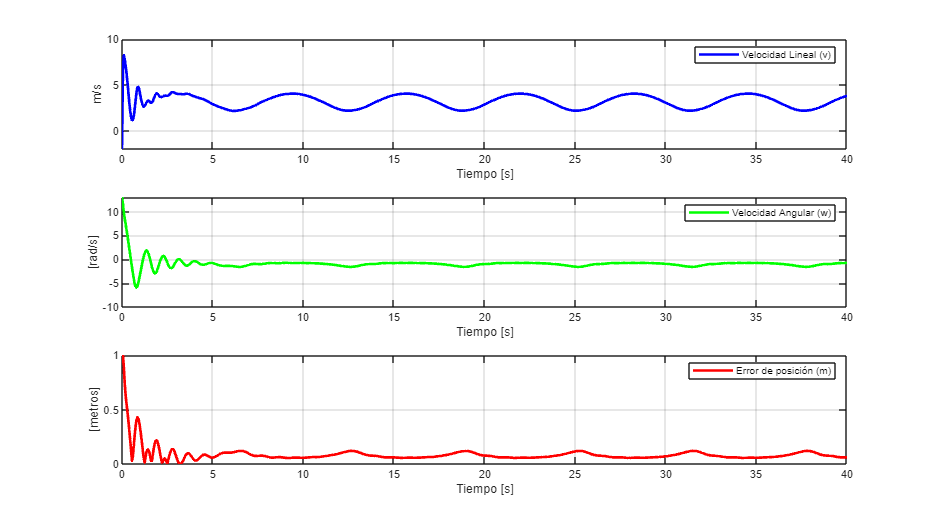

graph=figure;  % Crear figura
set(graph,'position',sizeScreen); % Configurar tamaño de la figura
subplot(311)
plot(t(1:N),v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:N),w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:N),Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

## **c) **$x=3\cos \left(t\right)-\cos \left(3t\right),y=4\sin \left(3t\right)$

### Tiempo

Se definen los parámetros temporales del experimento: duración total (`tf`), intervalo de muestreo (`ts`), y se genera el vector de tiempo (`t`) con su longitud total (`N`), que define la cantidad de pasos de simulación.

tf=7;             % Tiempo de simulación en segundos (s)
ts=0.01;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

### Condiciones iniciales

Se establecen las condiciones iniciales del robot: su posición en el plano (x, y) y su orientación (`phi`) medida en radianes. En este caso, el robot comienza en el origen apuntando hacia

x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

Inicialmente, la posición del punto de control del robot coincide con su posición actual (`hx`, `hy`).

hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

### Trayectoria Deseada

Ecuaciones paramétricas de la trayectoria deseada

hxd=3*cos(t)-cos(3*t);
hyd=4*sin(3*t);

%Velocidades de la trayectoria deseada
hxdp = diff(hxd) / ts;
hydp = diff(hyd) / ts;

% Para que hxdp y hydp tengan la misma longitud que t, añadimos el último valor
hxdp = [hxdp, hxdp(end)];
hydp = [hydp, hydp(end)];

### Control, bucle de simulación

Se implementa un bucle `for` que recorre todos los instantes de tiempo definidos en el vector `t`. Dentro de este ciclo, se realiza el cálculo de errores de posición, la matriz Jacobiana, las ganancias, y la ley de control para determinar las velocidades lineal y angular requeridas para que el robot siga la trayectoria deseada.

for k=1:N 

#### a) Errores de control

 Se calculan los errores de posición entre la trayectoria deseada y la actual.

    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

#### b) Matriz Jacobiana

 Se construye la matriz Jacobiana que transforma errores en el marco global a comandos de movimiento en el marco del robot.

    J=[cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];

#### c) Matriz de Ganancias

Se define una ganancia proporcional para corregir el error.

    K=[25 0; 0 25];

####  d) Velocidades deseadas

 Se obtienen las velocidades de la trayectoria de referencia.

    hdp=[hxdp(k);hydp(k)];

#### e) Ley de Control

 Calcula las velocidades de referencia para el robot, corrigiendo el error e incorporando la velocidad deseada.

    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 

#### Aplicación de Control al Robot

Una vez calculadas las velocidades de control, se aplican al modelo cinemático del robot mediante integración numérica (Método de Euler) para actualizar su posición y orientación en cada instante de tiempo.

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-5 5 -5 5 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

**b) Graficar robots en la posicion inicial**

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

**c) Graficar trayectorias**

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'c','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial

**d) Bucle de simulacion de movimiento del robot**

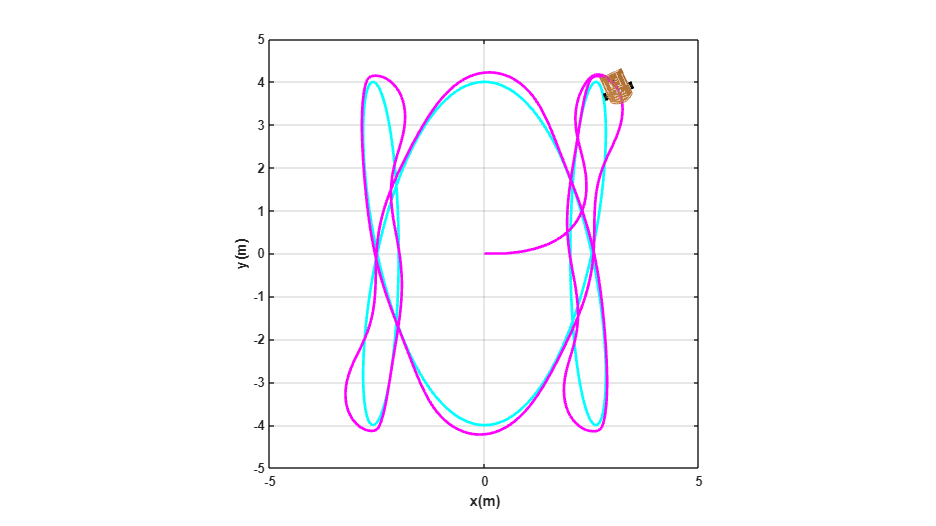

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'m','lineWidth',2);
    
    pause(ts);

end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

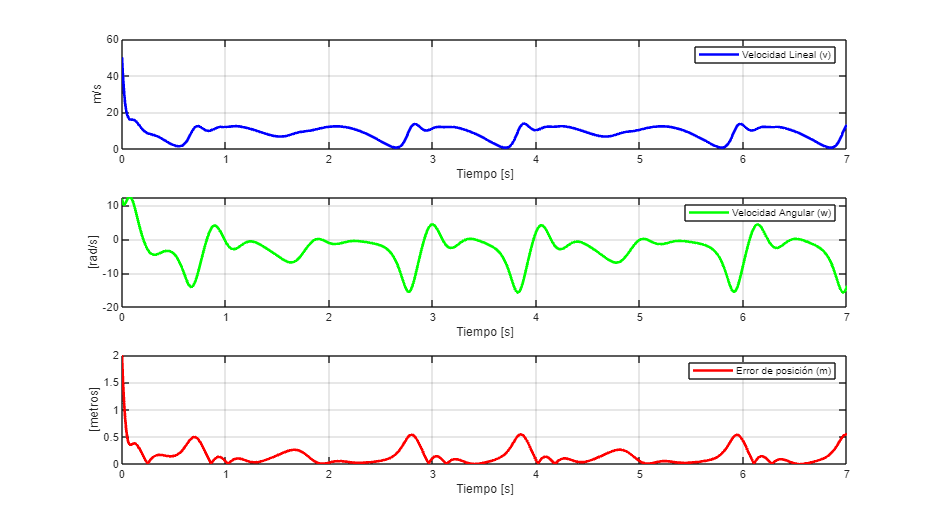

graph=figure;  % Crear figura
set(graph,'position',sizeScreen); % Configurar tamaño de la figura
subplot(311)
plot(t(1:N),v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:N),w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:N),Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

## **d) **$x=\cos \left(t\right)+\frac{1}{2}\cos \left(7t\right)+\frac{1}{3}\textrm{sen}\left(17t\right),y=\textrm{sen}\left(t\right)+\frac{1}{2}\textrm{sen}\left(7t\right)+\frac{1}{3}\cos \left(17t\right)$

### Tiempo

Se definen los parámetros temporales del experimento: duración total (`tf`), intervalo de muestreo (`ts`), y se genera el vector de tiempo (`t`) con su longitud total (`N`), que define la cantidad de pasos de simulación.

tf=7;             % Tiempo de simulación en segundos (s)
ts=0.01;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

### Condiciones iniciales

Se establecen las condiciones iniciales del robot: su posición en el plano (x, y) y su orientación (`phi`) medida en radianes. En este caso, el robot comienza en el origen apuntando hacia

x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

Inicialmente, la posición del punto de control del robot coincide con su posición actual (`hx`, `hy`).

hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

### Trayectoria Deseada

Ecuaciones paramétricas de la trayectoria deseada

hxd=cos(t)+1/2*cos(7*t)+1/3*sin(17*t);
hyd=sin(t)+1/2*sin(7*t)+1/3*cos(17*t);

%Velocidades de la trayectoria deseada
hxdp = diff(hxd) / ts;
hydp = diff(hyd) / ts;

% Para que hxdp y hydp tengan la misma longitud que t, añadimos el último valor
hxdp = [hxdp, hxdp(end)];
hydp = [hydp, hydp(end)];

### Control, bucle de simulación

Se implementa un bucle `for` que recorre todos los instantes de tiempo definidos en el vector `t`. Dentro de este ciclo, se realiza el cálculo de errores de posición, la matriz Jacobiana, las ganancias, y la ley de control para determinar las velocidades lineal y angular requeridas para que el robot siga la trayectoria deseada.

for k=1:N 

#### a) Errores de control

 Se calculan los errores de posición entre la trayectoria deseada y la actual.

    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

#### b) Matriz Jacobiana

 Se construye la matriz Jacobiana que transforma errores en el marco global a comandos de movimiento en el marco del robot.

    J=[cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];

#### c) Matriz de Ganancias

Se define una ganancia proporcional para corregir el error.

    K=[5 0; 0 5];

####  d) Velocidades deseadas

 Se obtienen las velocidades de la trayectoria de referencia.

    hdp=[hxdp(k);hydp(k)];

#### e) Ley de Control

 Calcula las velocidades de referencia para el robot, corrigiendo el error e incorporando la velocidad deseada.

    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 

#### Aplicación de Control al Robot

Una vez calculadas las velocidades de control, se aplican al modelo cinemático del robot mediante integración numérica (Método de Euler) para actualizar su posición y orientación en cada instante de tiempo.

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-2 2 -2 2 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

**b) Graficar robots en la posicion inicial**

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

**c) Graficar trayectorias**

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'c','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial

**d) Bucle de simulacion de movimiento del robot**

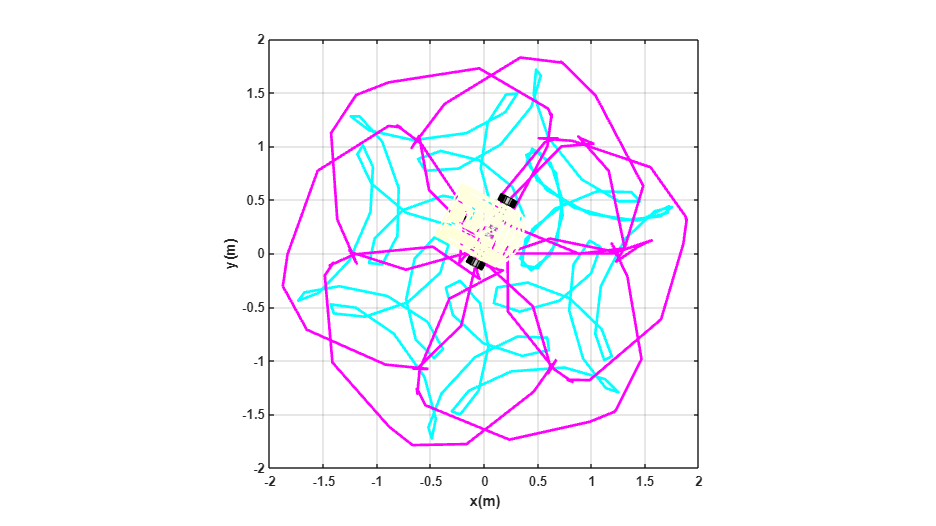

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'m','lineWidth',2);
    
    pause(ts);

end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

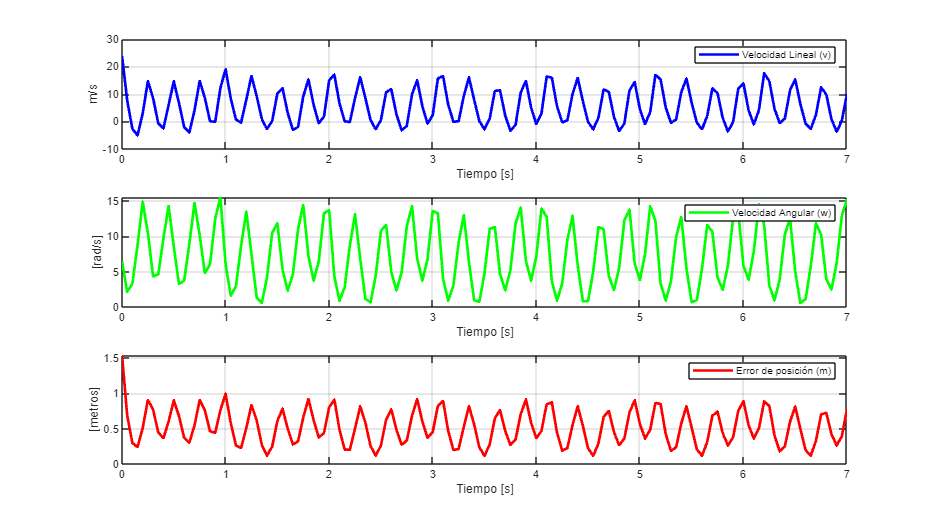

graph=figure;  % Crear figura
set(graph,'position',sizeScreen); % Configurar tamaño de la figura
subplot(311)
plot(t(1:N),v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:N),w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:N),Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

## **e) **$x=17\cos \left(t\right)+7\cos \left(17+7t\right),y=17\textrm{sen}\left(t\right)-7\textrm{sen}\left(17+7t\right)$

### Tiempo

Se definen los parámetros temporales del experimento: duración total (`tf`), intervalo de muestreo (`ts`), y se genera el vector de tiempo (`t`) con su longitud total (`N`), que define la cantidad de pasos de simulación.

tf=10;             % Tiempo de simulación en segundos (s)
ts=0.05;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

### Condiciones iniciales

Se establecen las condiciones iniciales del robot: su posición en el plano (x, y) y su orientación (`phi`) medida en radianes. En este caso, el robot comienza en el origen apuntando hacia

x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

Inicialmente, la posición del punto de control del robot coincide con su posición actual (`hx`, `hy`).

hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

### Trayectoria Deseada

Ecuaciones paramétricas de la trayectoria deseada

hxd=17*cos(t)+7*cos(17+7*t);
hyd=17*sin(t)-7*sin(17+7*t);

%Velocidades de la trayectoria deseada
hxdp = diff(hxd) / ts;
hydp = diff(hyd) / ts;

% Para que hxdp y hydp tengan la misma longitud que t, añadimos el último valor
hxdp = [hxdp, hxdp(end)];
hydp = [hydp, hydp(end)];

### Control, bucle de simulación

Se implementa un bucle `for` que recorre todos los instantes de tiempo definidos en el vector `t`. Dentro de este ciclo, se realiza el cálculo de errores de posición, la matriz Jacobiana, las ganancias, y la ley de control para determinar las velocidades lineal y angular requeridas para que el robot siga la trayectoria deseada.

for k=1:N 

#### a) Errores de control

 Se calculan los errores de posición entre la trayectoria deseada y la actual.

    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

#### b) Matriz Jacobiana

 Se construye la matriz Jacobiana que transforma errores en el marco global a comandos de movimiento en el marco del robot.

    J=[cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];

#### c) Matriz de Ganancias

Se define una ganancia proporcional para corregir el error.

    K=[13 0;...
       0 13];

####  d) Velocidades deseadas

 Se obtienen las velocidades de la trayectoria de referencia.

    hdp=[hxdp(k);hydp(k)];

#### e) Ley de Control

 Calcula las velocidades de referencia para el robot, corrigiendo el error e incorporando la velocidad deseada.

    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 

#### Aplicación de Control al Robot

Una vez calculadas las velocidades de control, se aplican al modelo cinemático del robot mediante integración numérica (Método de Euler) para actualizar su posición y orientación en cada instante de tiempo.

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-25 25 -25 25 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

**b) Graficar robots en la posicion inicial**

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

**c) Graficar trayectorias**

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'c','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial

**d) Bucle de simulacion de movimiento del robot**

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'m','lineWidth',2);
    
    pause(ts);

end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

graph=figure;  % Crear figura
set(graph,'position',sizeScreen); % Configurar tamaño de la figura
subplot(311)
plot(t(1:N),v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:N),w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:N),Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

## **f) **$x=2\cos \left(t\right),y=2\textrm{sen}\left(t\right)$

### Tiempo

Se definen los parámetros temporales del experimento: duración total (`tf`), intervalo de muestreo (`ts`), y se genera el vector de tiempo (`t`) con su longitud total (`N`), que define la cantidad de pasos de simulación.

tf=10;             % Tiempo de simulación en segundos (s)
ts=0.05;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

### Condiciones iniciales

Se establecen las condiciones iniciales del robot: su posición en el plano (x, y) y su orientación (`phi`) medida en radianes. En este caso, el robot comienza en el origen apuntando hacia

x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

Inicialmente, la posición del punto de control del robot coincide con su posición actual (`hx`, `hy`).

hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

### Trayectoria Deseada

Ecuaciones paramétricas de la trayectoria deseada

hxd=2*cos(t);
hyd=2*sin(t);

%Velocidades de la trayectoria deseada
hxdp = diff(hxd) / ts;
hydp = diff(hyd) / ts;

% Para que hxdp y hydp tengan la misma longitud que t, añadimos el último valor
hxdp = [hxdp, hxdp(end)];
hydp = [hydp, hydp(end)];

### Control, bucle de simulación

Se implementa un bucle `for` que recorre todos los instantes de tiempo definidos en el vector `t`. Dentro de este ciclo, se realiza el cálculo de errores de posición, la matriz Jacobiana, las ganancias, y la ley de control para determinar las velocidades lineal y angular requeridas para que el robot siga la trayectoria deseada.

for k=1:N 

#### a) Errores de control

 Se calculan los errores de posición entre la trayectoria deseada y la actual.

    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

#### b) Matriz Jacobiana

 Se construye la matriz Jacobiana que transforma errores en el marco global a comandos de movimiento en el marco del robot.

    J=[cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];

#### c) Matriz de Ganancias

Se define una ganancia proporcional para corregir el error.

    K=[13 0;...
       0 13];

####  d) Velocidades deseadas

 Se obtienen las velocidades de la trayectoria de referencia.

    hdp=[hxdp(k);hydp(k)];

#### e) Ley de Control

 Calcula las velocidades de referencia para el robot, corrigiendo el error e incorporando la velocidad deseada.

    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 

#### Aplicación de Control al Robot

Una vez calculadas las velocidades de control, se aplican al modelo cinemático del robot mediante integración numérica (Método de Euler) para actualizar su posición y orientación en cada instante de tiempo.

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-3 3 -3 3 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

**b) Graficar robots en la posicion inicial**

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

**c) Graficar trayectorias**

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'c','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial

**d) Bucle de simulacion de movimiento del robot**

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'m','lineWidth',2);
    
    pause(ts);

end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

graph=figure;  % Crear figura
set(graph,'position',sizeScreen); % Configurar tamaño de la figura
subplot(311)
plot(t(1:N),v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:N),w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:N),Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

## **g) **$x=5t-4\textrm{sen}\left(t\right),y=5t-4\cos \left(t\right)$

### Tiempo

Se definen los parámetros temporales del experimento: duración total (`tf`), intervalo de muestreo (`ts`), y se genera el vector de tiempo (`t`) con su longitud total (`N`), que define la cantidad de pasos de simulación.

tf=15;             % Tiempo de simulación en segundos (s)
ts=0.05;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

### Condiciones iniciales

Se establecen las condiciones iniciales del robot: su posición en el plano (x, y) y su orientación (`phi`) medida en radianes. En este caso, el robot comienza en el origen apuntando hacia

x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

Inicialmente, la posición del punto de control del robot coincide con su posición actual (`hx`, `hy`).

hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

### Trayectoria Deseada

Ecuaciones paramétricas de la trayectoria deseada

hxd=5*t-4*sin(t);
hyd=5*t-4*cos(t);

%Velocidades de la trayectoria deseada
hxdp = diff(hxd) / ts;
hydp = diff(hyd) / ts;

% Para que hxdp y hydp tengan la misma longitud que t, añadimos el último valor
hxdp = [hxdp, hxdp(end)];
hydp = [hydp, hydp(end)];

### Control, bucle de simulación

Se implementa un bucle `for` que recorre todos los instantes de tiempo definidos en el vector `t`. Dentro de este ciclo, se realiza el cálculo de errores de posición, la matriz Jacobiana, las ganancias, y la ley de control para determinar las velocidades lineal y angular requeridas para que el robot siga la trayectoria deseada.

for k=1:N 

#### a) Errores de control

 Se calculan los errores de posición entre la trayectoria deseada y la actual.

    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

#### b) Matriz Jacobiana

 Se construye la matriz Jacobiana que transforma errores en el marco global a comandos de movimiento en el marco del robot.

    J=[cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];

#### c) Matriz de Ganancias

Se define una ganancia proporcional para corregir el error.

    K=[13 0;...
       0 13];

####  d) Velocidades deseadas

 Se obtienen las velocidades de la trayectoria de referencia.

    hdp=[hxdp(k);hydp(k)];

#### e) Ley de Control

 Calcula las velocidades de referencia para el robot, corrigiendo el error e incorporando la velocidad deseada.

    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 

#### Aplicación de Control al Robot

Una vez calculadas las velocidades de control, se aplican al modelo cinemático del robot mediante integración numérica (Método de Euler) para actualizar su posición y orientación en cada instante de tiempo.

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-10 80 -10 80 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

**b) Graficar robots en la posicion inicial**

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

**c) Graficar trayectorias**

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'c','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial

**d) Bucle de simulacion de movimiento del robot**

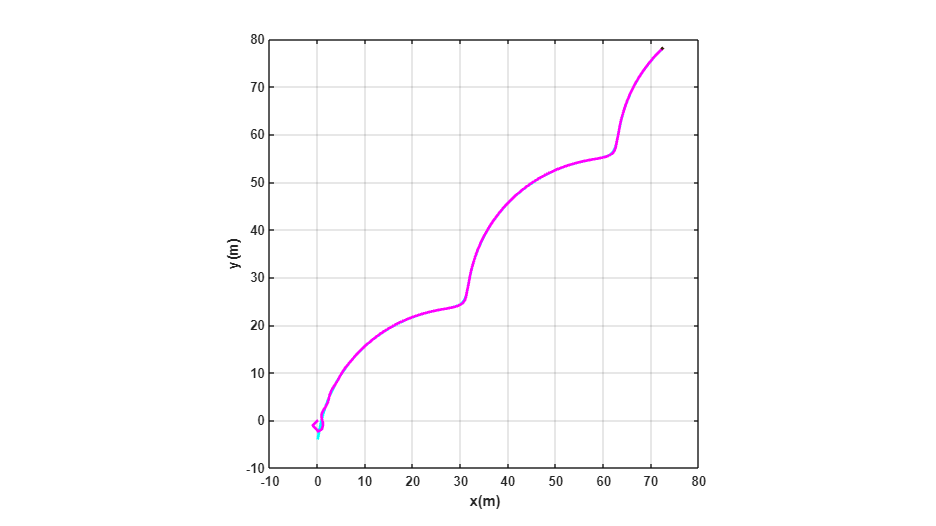

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'m','lineWidth',2);
    
    pause(ts);

end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

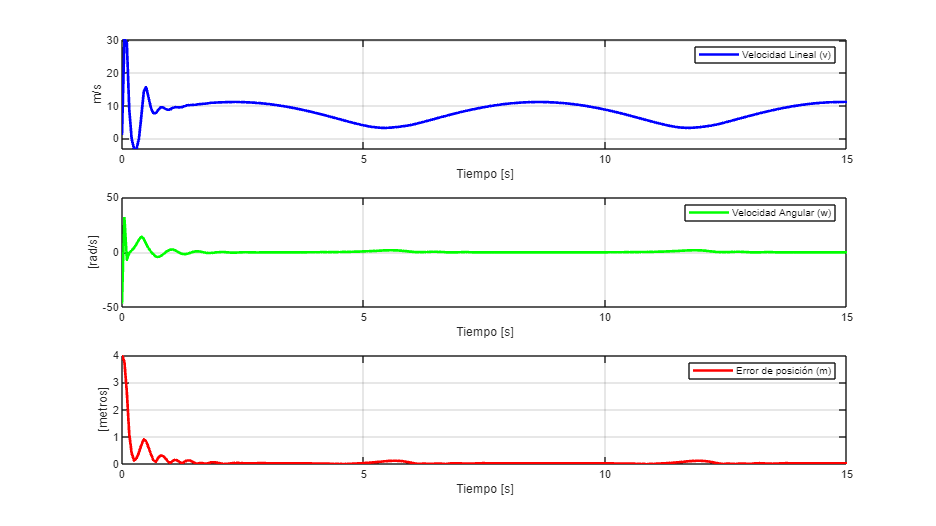

graph=figure;  % Crear figura
set(graph,'position',sizeScreen); % Configurar tamaño de la figura
subplot(311)
plot(t(1:N),v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:N),w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:N),Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

## **h) **$x=4\cos \left(t\right)+\cos \left(4t\right),y=4\textrm{sen}\left(t\right)-\textrm{sen}\left(4t\right)$

### Tiempo

Se definen los parámetros temporales del experimento: duración total (`tf`), intervalo de muestreo (`ts`), y se genera el vector de tiempo (`t`) con su longitud total (`N`), que define la cantidad de pasos de simulación.

tf=7;             % Tiempo de simulación en segundos (s)
ts=0.05;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

### Condiciones iniciales

Se establecen las condiciones iniciales del robot: su posición en el plano (x, y) y su orientación (`phi`) medida en radianes. En este caso, el robot comienza en el origen apuntando hacia

x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

Inicialmente, la posición del punto de control del robot coincide con su posición actual (`hx`, `hy`).

hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

### Trayectoria Deseada

Ecuaciones paramétricas de la trayectoria deseada

hxd=4*cos(t)+cos(4*t);
hyd=4*sin(t)-sin(4*t);

%Velocidades de la trayectoria deseada
hxdp = diff(hxd) / ts;
hydp = diff(hyd) / ts;

% Para que hxdp y hydp tengan la misma longitud que t, añadimos el último valor
hxdp = [hxdp, hxdp(end)];
hydp = [hydp, hydp(end)];

### Control, bucle de simulación

Se implementa un bucle `for` que recorre todos los instantes de tiempo definidos en el vector `t`. Dentro de este ciclo, se realiza el cálculo de errores de posición, la matriz Jacobiana, las ganancias, y la ley de control para determinar las velocidades lineal y angular requeridas para que el robot siga la trayectoria deseada.

for k=1:N 

#### a) Errores de control

 Se calculan los errores de posición entre la trayectoria deseada y la actual.

    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

#### b) Matriz Jacobiana

 Se construye la matriz Jacobiana que transforma errores en el marco global a comandos de movimiento en el marco del robot.

    J=[cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];

#### c) Matriz de Ganancias

Se define una ganancia proporcional para corregir el error.

    K=[13 0;...
       0 13];

####  d) Velocidades deseadas

 Se obtienen las velocidades de la trayectoria de referencia.

    hdp=[hxdp(k);hydp(k)];

#### e) Ley de Control

 Calcula las velocidades de referencia para el robot, corrigiendo el error e incorporando la velocidad deseada.

    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 

#### Aplicación de Control al Robot

Una vez calculadas las velocidades de control, se aplican al modelo cinemático del robot mediante integración numérica (Método de Euler) para actualizar su posición y orientación en cada instante de tiempo.

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-5 5 -5 5 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

**b) Graficar robots en la posicion inicial**

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

**c) Graficar trayectorias**

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'c','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial

**d) Bucle de simulacion de movimiento del robot**

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'m','lineWidth',2);
    
    pause(ts);

end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

graph=figure;  % Crear figura
set(graph,'position',sizeScreen); % Configurar tamaño de la figura
subplot(311)
plot(t(1:N),v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:N),w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:N),Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

## Hexágono

### Tiempo

Se definen los parámetros temporales del experimento: duración total (`tf`), intervalo de muestreo (`ts`), y se genera el vector de tiempo (`t`) con su longitud total (`N`), que define la cantidad de pasos de simulación.

tf=40;             % Tiempo de simulación en segundos (s)
ts=0.05;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

### Condiciones iniciales

Se establecen las condiciones iniciales del robot: su posición en el plano (x, y) y su orientación (`phi`) medida en radianes. En este caso, el robot comienza en el origen apuntando hacia

x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

Inicialmente, la posición del punto de control del robot coincide con su posición actual (`hx`, `hy`).

hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

### Trayectoria Deseada

Ecuaciones paramétricas de la trayectoria deseada

% Parámetros del hexágono
lados = 6;
r = 1; % radio
theta = linspace(0, 2*pi, lados+1); % 7 puntos (el último repite el primero)

% Coordenadas de los vértices
vx = r * cos(theta);
vy = r * sin(theta);

% Índices de tiempo para cada vértice
idx_puntos = round(linspace(1, N, lados+1)); % puntos en el vector de tiempo

% Interpolación de la trayectoria deseada
hxd = interp1(idx_puntos, vx, 1:N, 'linear');
hyd = interp1(idx_puntos, vy, 1:N, 'linear');

%Velocidades de la trayectoria deseada
hxdp = diff(hxd) / ts;
hydp = diff(hyd) / ts;

% Para que hxdp y hydp tengan la misma longitud que t, añadimos el último valor
hxdp = [hxdp, hxdp(end)];
hydp = [hydp, hydp(end)];

### Control, bucle de simulación

Se implementa un bucle `for` que recorre todos los instantes de tiempo definidos en el vector `t`. Dentro de este ciclo, se realiza el cálculo de errores de posición, la matriz Jacobiana, las ganancias, y la ley de control para determinar las velocidades lineal y angular requeridas para que el robot siga la trayectoria deseada.

for k=1:N 

#### a) Errores de control

 Se calculan los errores de posición entre la trayectoria deseada y la actual.

    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

#### b) Matriz Jacobiana

 Se construye la matriz Jacobiana que transforma errores en el marco global a comandos de movimiento en el marco del robot.

    J=[cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];

#### c) Matriz de Ganancias

Se define una ganancia proporcional para corregir el error.

    K=[13 0;...
       0 13];

####  d) Velocidades deseadas

 Se obtienen las velocidades de la trayectoria de referencia.

    hdp=[hxdp(k);hydp(k)];

#### e) Ley de Control

 Calcula las velocidades de referencia para el robot, corrigiendo el error e incorporando la velocidad deseada.

    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 

#### Aplicación de Control al Robot

Una vez calculadas las velocidades de control, se aplican al modelo cinemático del robot mediante integración numérica (Método de Euler) para actualizar su posición y orientación en cada instante de tiempo.

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-1.5 1.5 -1.5 1.5 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

**b) Graficar robots en la posicion inicial**

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

**c) Graficar trayectorias**

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'c','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial

**d) Bucle de simulacion de movimiento del robot**

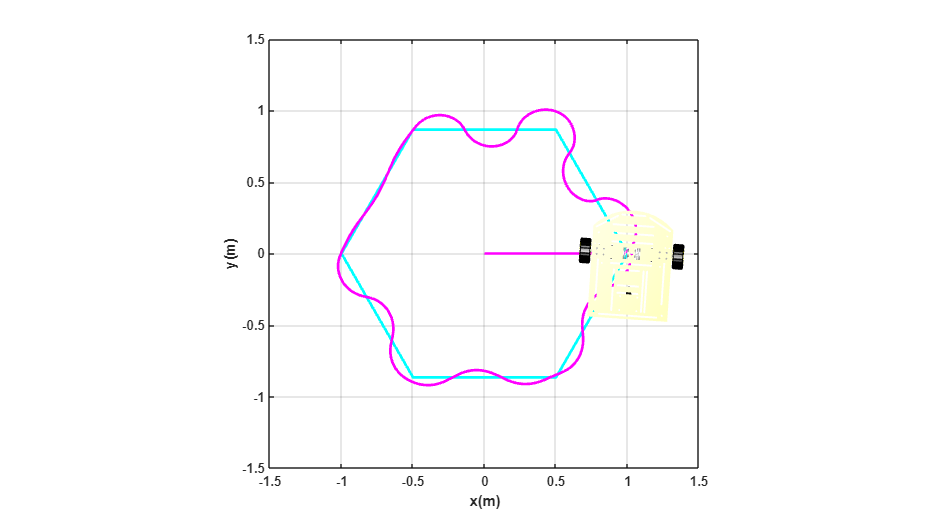

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'m','lineWidth',2);
    
    pause(ts);

end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

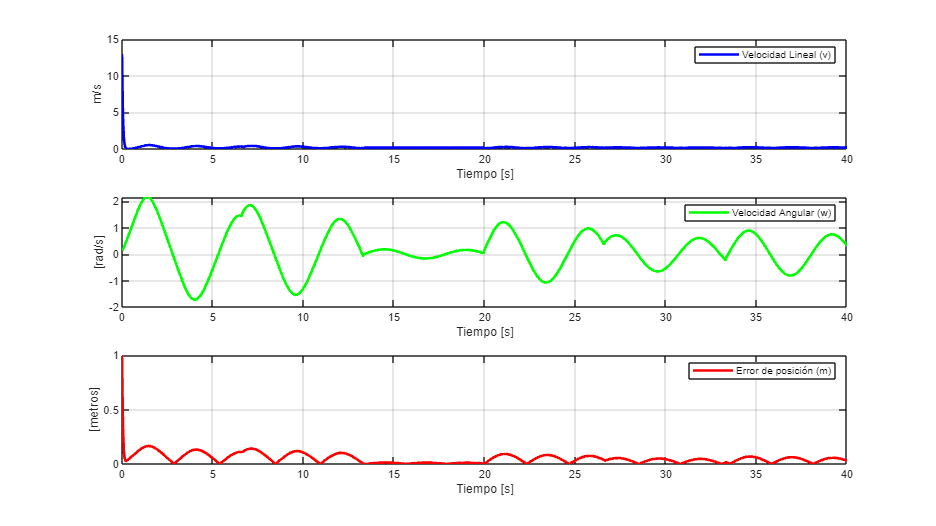

graph=figure;  % Crear figura
set(graph,'position',sizeScreen); % Configurar tamaño de la figura
subplot(311)
plot(t(1:N),v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:N),w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:N),Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

## Flor

### Tiempo

Se definen los parámetros temporales del experimento: duración total (`tf`), intervalo de muestreo (`ts`), y se genera el vector de tiempo (`t`) con su longitud total (`N`), que define la cantidad de pasos de simulación.

tf=6.6;             % Tiempo de simulación en segundos (s)
ts=0.05;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

### Condiciones iniciales

Se establecen las condiciones iniciales del robot: su posición en el plano (x, y) y su orientación (`phi`) medida en radianes. En este caso, el robot comienza en el origen apuntando hacia

x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

Inicialmente, la posición del punto de control del robot coincide con su posición actual (`hx`, `hy`).

hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

### Trayectoria Deseada

Ecuaciones paramétricas de la trayectoria deseada

hxd=50*cos(8*t).*cos(t);
hyd=50*cos(8*t).*sin(t);

%Velocidades de la trayectoria deseada
hxdp = diff(hxd) / ts;
hydp = diff(hyd) / ts;

% Para que hxdp y hydp tengan la misma longitud que t, añadimos el último valor
hxdp = [hxdp, hxdp(end)];
hydp = [hydp, hydp(end)];

### Control, bucle de simulación

Se implementa un bucle `for` que recorre todos los instantes de tiempo definidos en el vector `t`. Dentro de este ciclo, se realiza el cálculo de errores de posición, la matriz Jacobiana, las ganancias, y la ley de control para determinar las velocidades lineal y angular requeridas para que el robot siga la trayectoria deseada.

for k=1:N 

#### a) Errores de control

 Se calculan los errores de posición entre la trayectoria deseada y la actual.

    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

#### b) Matriz Jacobiana

 Se construye la matriz Jacobiana que transforma errores en el marco global a comandos de movimiento en el marco del robot.

    J=[cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];

#### c) Matriz de Ganancias

Se define una ganancia proporcional para corregir el error.

    K=[13 0;...
       0 13];

####  d) Velocidades deseadas

 Se obtienen las velocidades de la trayectoria de referencia.

    hdp=[hxdp(k);hydp(k)];

#### e) Ley de Control

 Calcula las velocidades de referencia para el robot, corrigiendo el error e incorporando la velocidad deseada.

    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 

#### Aplicación de Control al Robot

Una vez calculadas las velocidades de control, se aplican al modelo cinemático del robot mediante integración numérica (Método de Euler) para actualizar su posición y orientación en cada instante de tiempo.

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-50 50 -50 50 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

**b) Graficar robots en la posicion inicial**

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

**c) Graficar trayectorias**

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'c','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial

**d) Bucle de simulacion de movimiento del robot**

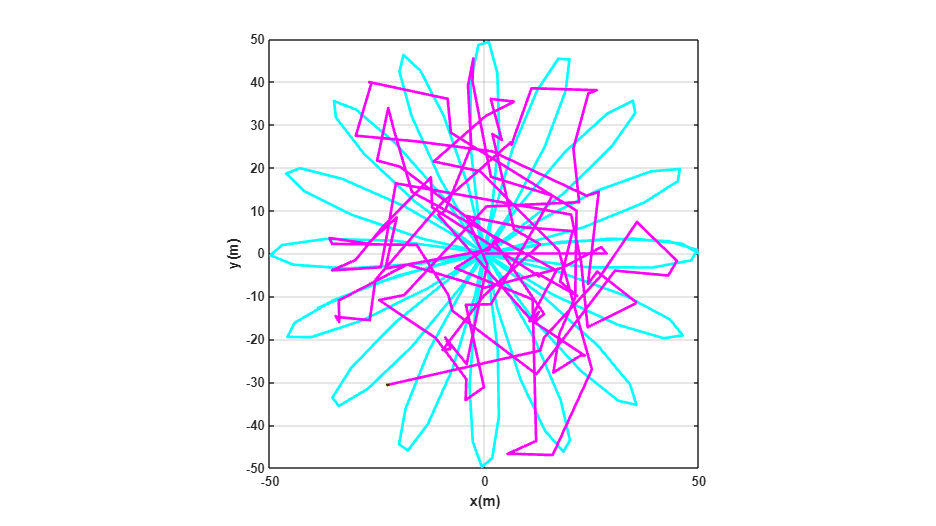

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'m','lineWidth',2);
    
    pause(ts);

end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

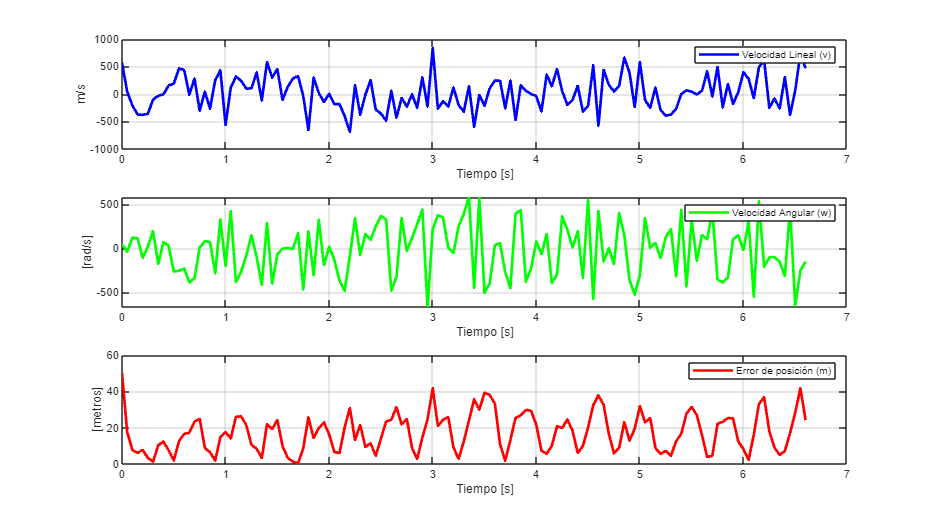

graph=figure;  % Crear figura
set(graph,'position',sizeScreen); % Configurar tamaño de la figura
subplot(311)
plot(t(1:N),v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:N),w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:N),Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

## Corazón

### Tiempo

Se definen los parámetros temporales del experimento: duración total (`tf`), intervalo de muestreo (`ts`), y se genera el vector de tiempo (`t`) con su longitud total (`N`), que define la cantidad de pasos de simulación.

tf=10;             % Tiempo de simulación en segundos (s)
ts=0.05;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

### Condiciones iniciales

Se establecen las condiciones iniciales del robot: su posición en el plano (x, y) y su orientación (`phi`) medida en radianes. En este caso, el robot comienza en el origen apuntando hacia

x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

Inicialmente, la posición del punto de control del robot coincide con su posición actual (`hx`, `hy`).

hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

### Trayectoria Deseada

Ecuaciones paramétricas de la trayectoria deseada

hxd= 15*(sin(t)).^3;
hyd = 15*cos(t)-5*cos(2*t)-2*cos(3*t);


%Velocidades de la trayectoria deseada
hxdp = diff(hxd) / ts;
hydp = diff(hyd) / ts;

% Para que hxdp y hydp tengan la misma longitud que t, añadimos el último valor
hxdp = [hxdp, hxdp(end)];
hydp = [hydp, hydp(end)];

### Control, bucle de simulación

Se implementa un bucle `for` que recorre todos los instantes de tiempo definidos en el vector `t`. Dentro de este ciclo, se realiza el cálculo de errores de posición, la matriz Jacobiana, las ganancias, y la ley de control para determinar las velocidades lineal y angular requeridas para que el robot siga la trayectoria deseada.

for k=1:N 

#### a) Errores de control

 Se calculan los errores de posición entre la trayectoria deseada y la actual.

    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

#### b) Matriz Jacobiana

 Se construye la matriz Jacobiana que transforma errores en el marco global a comandos de movimiento en el marco del robot.

    J=[cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];

#### c) Matriz de Ganancias

Se define una ganancia proporcional para corregir el error.

    K=[13 0;...
       0 13];

####  d) Velocidades deseadas

 Se obtienen las velocidades de la trayectoria de referencia.

    hdp=[hxdp(k);hydp(k)];

#### e) Ley de Control

 Calcula las velocidades de referencia para el robot, corrigiendo el error e incorporando la velocidad deseada.

    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 

#### Aplicación de Control al Robot

Una vez calculadas las velocidades de control, se aplican al modelo cinemático del robot mediante integración numérica (Método de Euler) para actualizar su posición y orientación en cada instante de tiempo.

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-20 20 -20 20 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

**b) Graficar robots en la posicion inicial**

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

**c) Graficar trayectorias**

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'c','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial

**d) Bucle de simulacion de movimiento del robot**

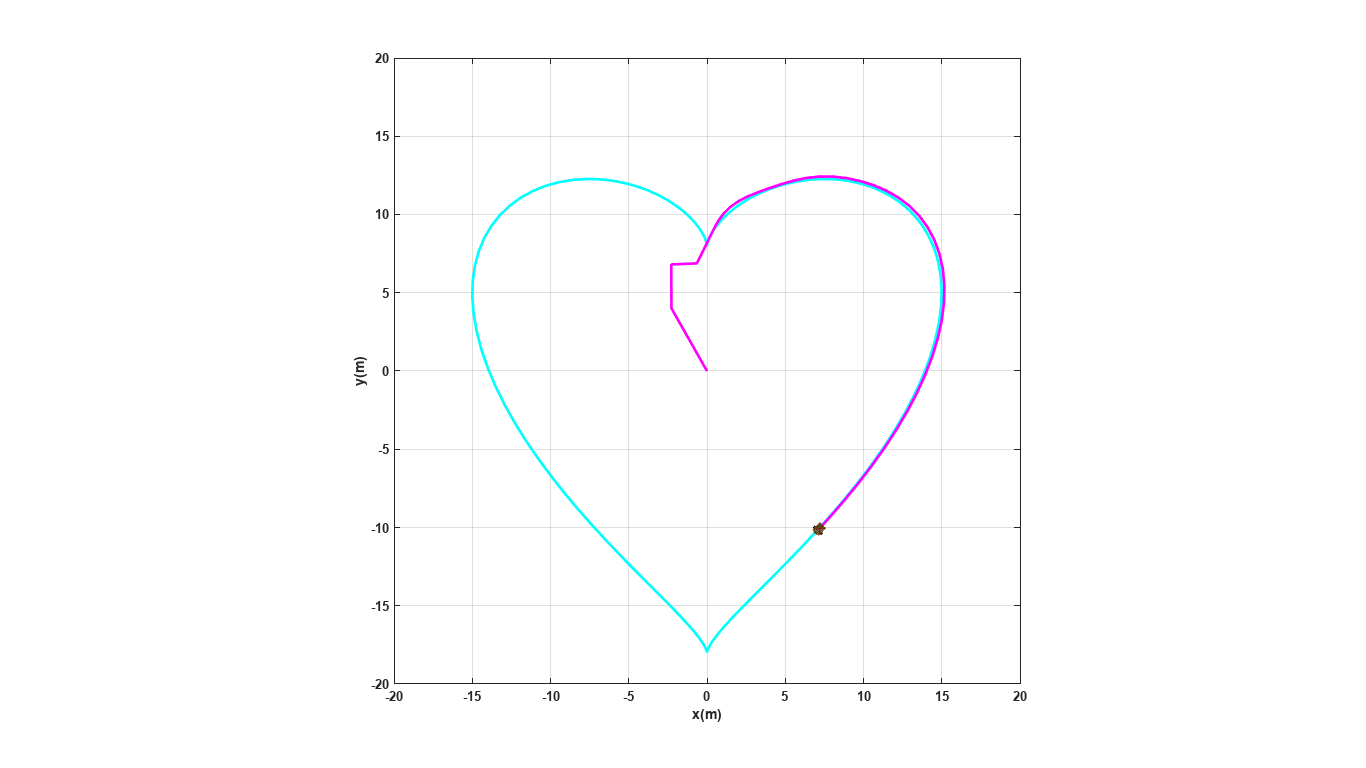

General Error occurred in WebControllerFactory::create()


step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'m','lineWidth',2);
    
    pause(ts);

end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

graph=figure;  % Crear figura
set(graph,'position',sizeScreen); % Configurar tamaño de la figura
subplot(311)
plot(t(1:N),v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:N),w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:N),Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');